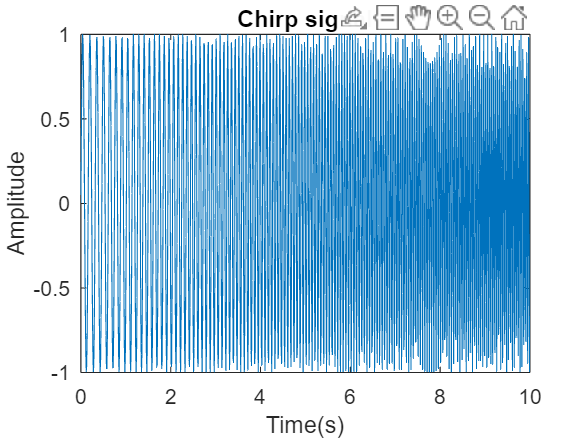

alpha =  1 + mod(19, 3);
% Generate chirp signal
fs =1024;
alpha = 2; % chirp rate
F_start = 2 + 2*alpha;
F_end = 5 + 5*alpha;
slope = (F_end-F_start)/10;
Ts = 1/100; % sampling period
t = 0:Ts:10-Ts;
F = F_start + slope*t;
x = sin(2*pi*F.*t);

plot(t,x);
xlabel('Time(s)')
ylabel("Amplitude")
title('Chirp signal')

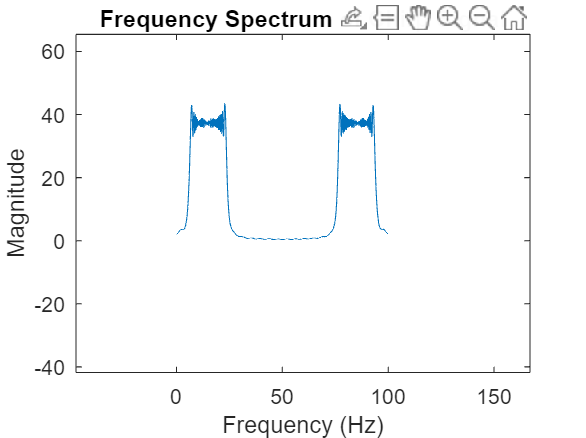

Nfft = 1024; % number of FFT points
X = fft(x, Nfft);
f = linspace(0, 1/Ts, Nfft);
plot(f, abs(X));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum of Chirp Signal');

a=1+ mod(19,3);
%1st a
t=linspace(0,2,241);
n=1024

n = 1024

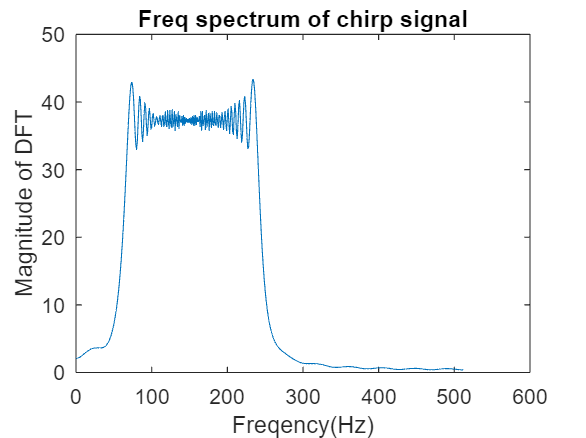

%stem(t,s);
ft = fft(x,1024);
k=abs(ft(1:n/2+1));
f=[0:fs/n:fs/2];
plot(f,k)
xlabel("Freqency(Hz)")
ylabel("Magnitude of DFT")
title ('Freq spectrum of chirp signal');

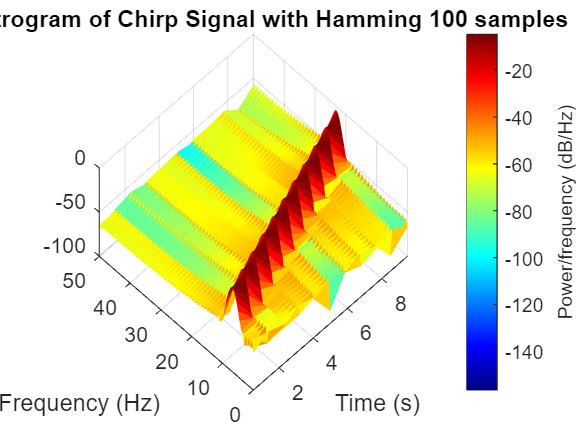

figure;
spectrogram(x, hamming(100), 10, 200, 100,"yaxis");view(-45,65);colormap jet
title('Spectrogram of Chirp Signal with Hamming 100 samples');

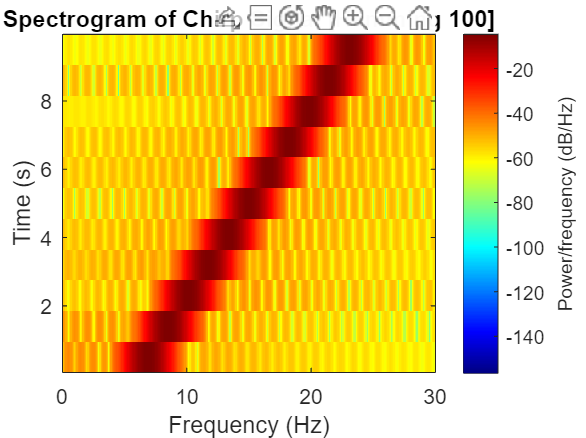

spectrogram(x, hamming(100), 10, 1024, 100)
xlim([0 30])
title('Spectrogram of Chirp Signal [Hamming 100]');

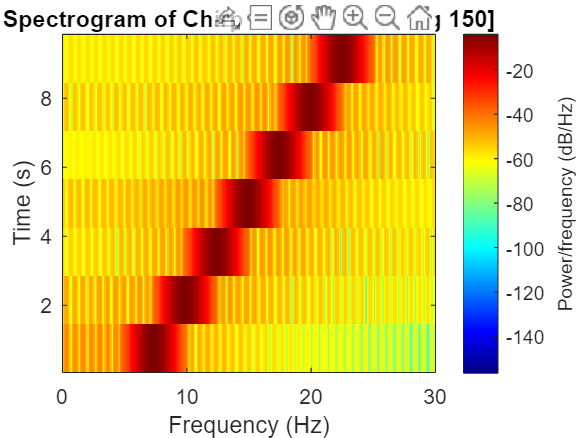

spectrogram(x, hamming(150), 10, 1024, 100)
xlim([0 30])
title('Spectrogram of Chirp Signal [Hamming 150]');

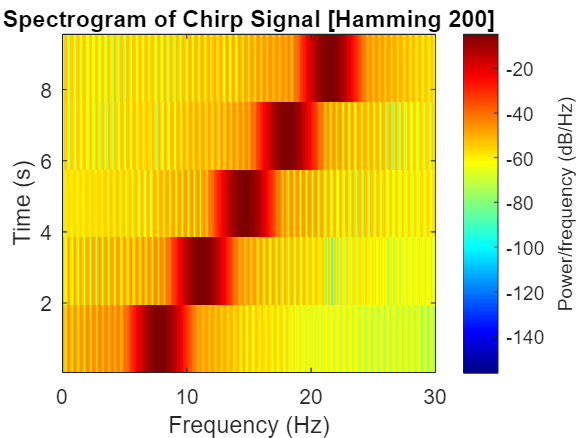

spectrogram(x, hamming(200), 10,1024,100)
xlim([0 30])
title('Spectrogram of Chirp Signal [Hamming 200]');

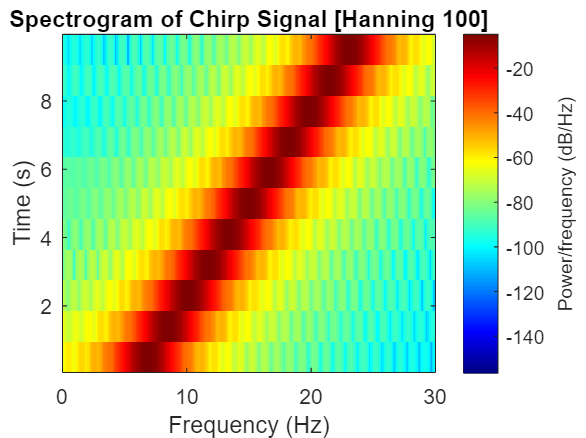

spectrogram(x, hanning(100), 10, 1024, 100)
xlim([0 30])
title('Spectrogram of Chirp Signal [Hanning 100]');

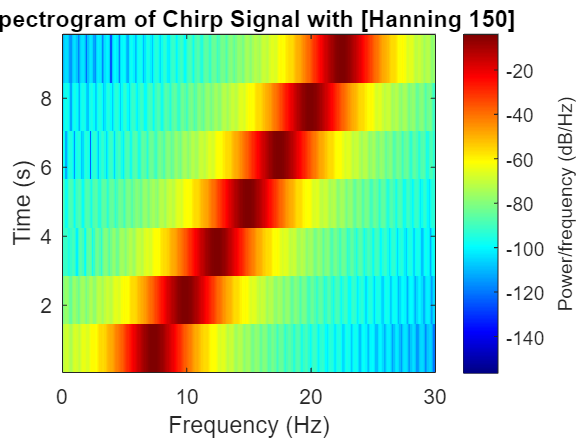

spectrogram(x, hanning(150), 10, 1024, 100)
xlim([0 30])
title('Spectrogram of Chirp Signal with [Hanning 150]');

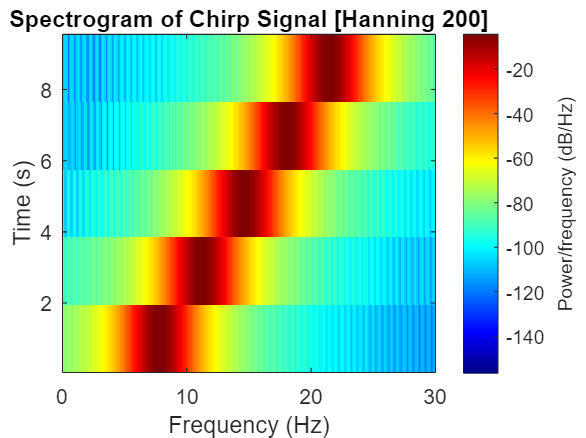

spectrogram(x, hanning(200), 10, 1024, 100)
xlim([0 30])
title('Spectrogram of Chirp Signal [Hanning 200]');

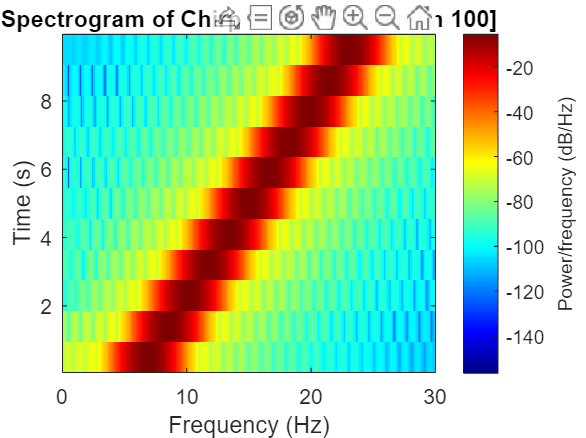

spectrogram(x, blackman(100), 10, 1024, 100);colormap jet
xlim([0 30])
title('Spectrogram of Chirp Signal [Blackman 100]');

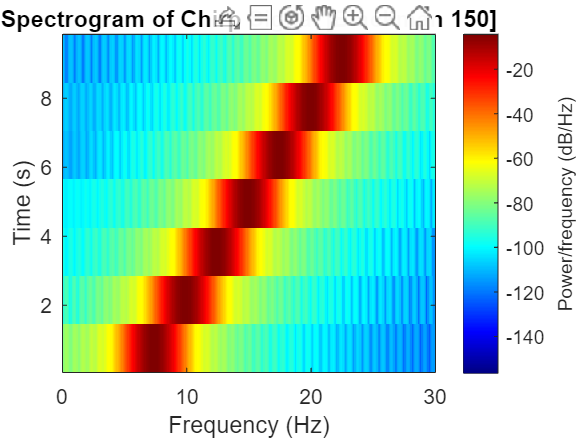

spectrogram(x, blackman(150), 10, 1024, 100)
xlim([0 30])
title('Spectrogram of Chirp Signal [Blackman 150]');

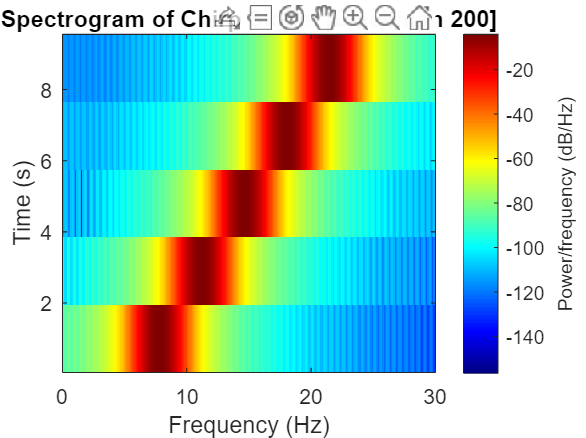

spectrogram(x, blackman(200), 10, 1024, 100)
xlim([0 30])
title('Spectrogram of Chirp Signal [Blackman 200]');

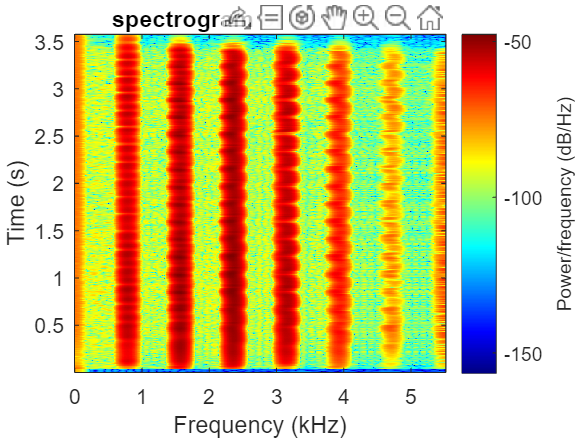

%% 2nd
[y,Fs] = audioread("instru2.wav");
spectrogram(y, hamming(100), 10, 1024, Fs);colormap jet
title("spectrogram of instru2 file")

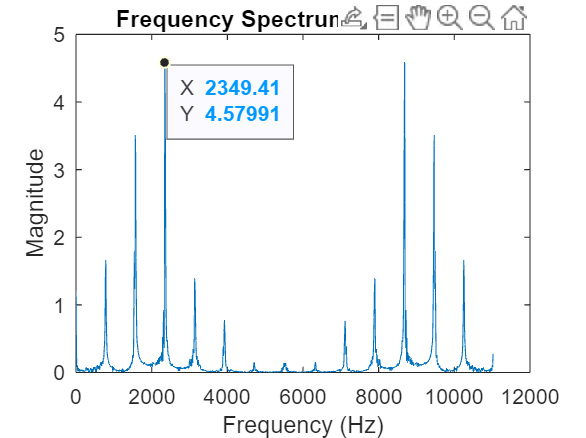


figure;
Nfft = 1024; 
X = fft(y, Nfft);
f = linspace(0, Fs, Nfft);
plot(f, abs(X));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum of instru file');

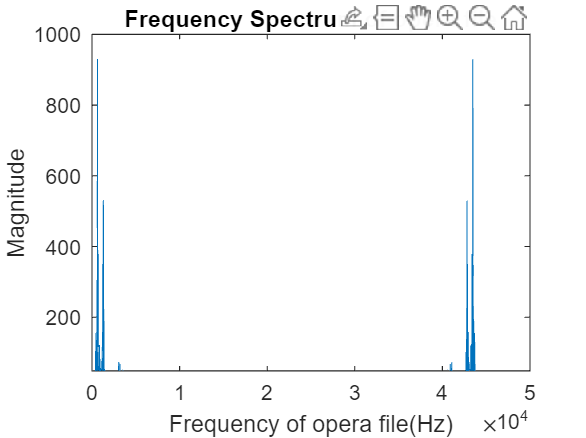

[yo,Fs] = audioread("Opera.wav");
Nfft = length(yo); 
X = fft(yo, Nfft);
f = linspace(0, Fs, Nfft);
plot(f, abs(X));
xlabel('Frequency of opera file(Hz)');
ylabel('Magnitude');
title ('Frequency Spectrum of opera file')

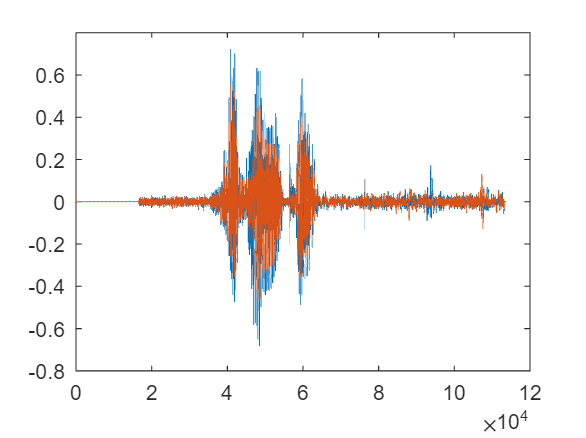

[h, Fs2] = audioread("my name.wav");
plot(h)

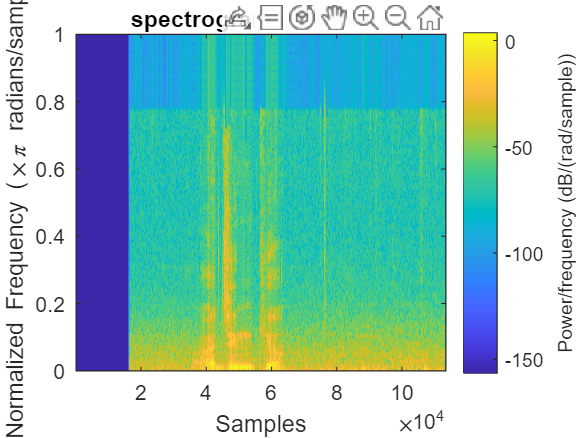

spectrogram(h(:,2),hamming(300),150,4000,'yaxis')
title("spectrogram of Ajinkya name")

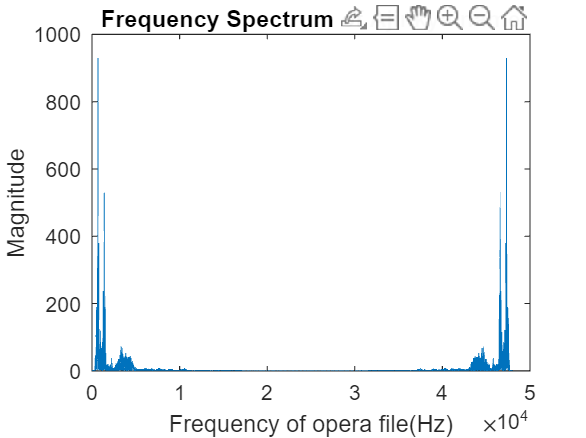

[h,Fs] = audioread("my name.wav");
Nfft = length(yo); 
X = fft(yo, Nfft);
f = linspace(0, Fs, Nfft);
plot(f, abs(X));
xlabel('Frequency of opera file(Hz)');
ylabel('Magnitude');
title (['Frequency Spectrum of Ajinkya name'])